% Jeremiah Sullivan. EC602. October 2019

% Script to call Python function and perform basic data analysis and
% simultaneously output the buffer to a file
clc; close all; clear all;


## Record Audio

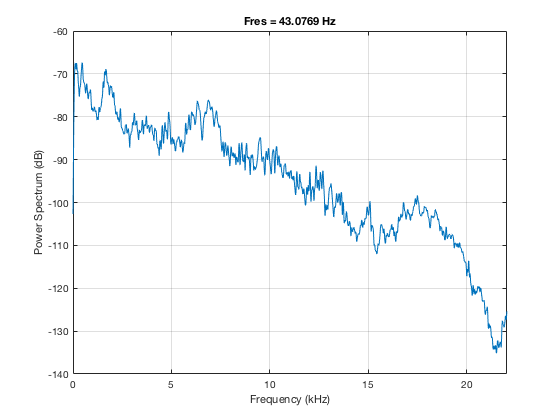


fs = 44.1E3; bitDepth = 24; 
recorder = audiorecorder(fs, bitDepth, 1, 0); 
recorder.record; 
pause(2); 
recorder.stop; 
yAmbient = recorder.getaudiodata; 
figure; pspectrum(yAmbient, fs); 

recorder.delete; 
recorder = audiorecorder(fs, bitDepth, 1, 0); 
recorder.record; 
tic;


## Run Chirp


pythonDir               = '/usr/local/bin/python3'; 
messengerScript     = '/Users/JP-Macbook/Documents/ec601/chirp/EC601-A2-Acoustic-Comm/messenger.py'; 
cmd                        = sprintf('%s %s -m abcdefghijk --wait %d', pythonDir, messengerScript, 10); 
tStart = toc; 

[status, result]        = system(cmd); 
    % Append "&" to skip waiting for the output
 result2 = strsplit(result, '\n');
 msg     = regexp(result2, '(?<=Received: ).*', 'match');
 inds    = ~cellfun(@isempty, msg); 
 tStop  = str2double(regexpi(result,  '(?<=Receiving message....[^"]*)\d+?(?= s of)', 'match', 'once')); 
 fprintf('\nUsing the Chirp App on my phone, I sent the following message,\nbeginning about %02.0f seconds into the recording: \n  ', tStart + tStop)


Using the Chirp App on my phone, I sent the following message,
beginning about 08 seconds into the recording: 
  

 cellfun(@disp, msg(inds)); 

    'abcdefghijklmnopqrstuvwxyzABCDEF'



## Analyze Signals

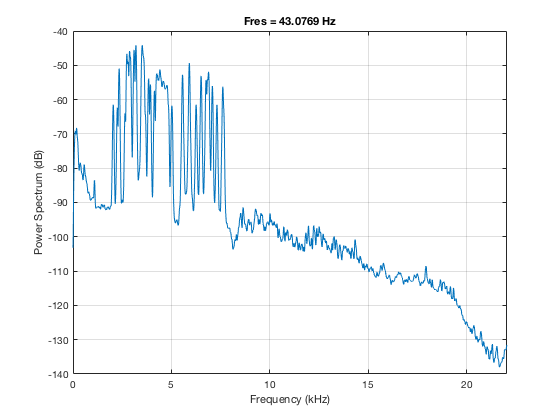

 recorder.stop; 
 y     = recorder.getaudiodata; 
 fs    = recorder.SampleRate; 
 figure; pspectrum(y, fs); 

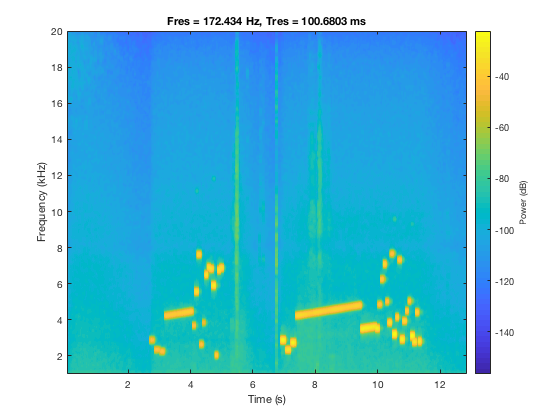

 figure; pspectrum(y, fs, 'spectrogram', 'frequencylimits', [1E3, 20E3])

## Conclusions

The LFM slide seems to correspond to the main message payload, for both the sent and recieved

There were no observed errors in sending or recieving any data. 

Questions:

    - The send payload package (~2s to 5s), was expected to be at 16 kHz. Why is this not the case?

        - Previously was unclear if the App could decode multiple frequencies... '

        - Now appears "messenger.py" may simple not be setting the range properly

    - The recieved payload package (via the Chirp app (Google Play), appeared to be at the same frequencies (2-8 kHz)

        - Makes me believe everythign is simply using the "standard" frequency regime